Hour = [6; 7; 8; 9; 10; 11; 12; 13; 14; 15; 16; 17];
SolarGen = [0.5; 1.2; 2.4; 3.8; 4.6; 5.1; 5.4; 5.0; 4.2; 3.0; 1.7; 0.8];
Demand = [1.8; 2.0; 2.3; 2.7; 3.1; 3.4; 3.8; 4.0; 3.7; 3.4; 3.0; 2.5];
Battery = [3.2; 3.0; 3.1; 3.8; 4.5; 5.2; 5.9; 6.3; 6.5; 6.1; 5.4; 4.7];

A = [Hour, SolarGen, Demand, Battery]

A =     6.0000    0.5000    1.8000    3.2000
    7.0000    1.2000    2.0000    3.0000
    8.0000    2.4000    2.3000    3.1000
    9.0000    3.8000    2.7000    3.8000
   10.0000    4.6000    3.1000    4.5000
   11.0000    5.1000    3.4000    5.2000
   12.0000    5.4000    3.8000    5.9000
   13.0000    5.0000    4.0000    6.3000
   14.0000    4.2000    3.7000    6.5000
   15.0000    3.0000    3.4000    6.1000



writematrix(A, 'solar_system.txt');
B = load('solar_system.txt')

B =     6.0000    0.5000    1.8000    3.2000
    7.0000    1.2000    2.0000    3.0000
    8.0000    2.4000    2.3000    3.1000
    9.0000    3.8000    2.7000    3.8000
   10.0000    4.6000    3.1000    4.5000
   11.0000    5.1000    3.4000    5.2000
   12.0000    5.4000    3.8000    5.9000
   13.0000    5.0000    4.0000    6.3000
   14.0000    4.2000    3.7000    6.5000
   15.0000    3.0000    3.4000    6.1000


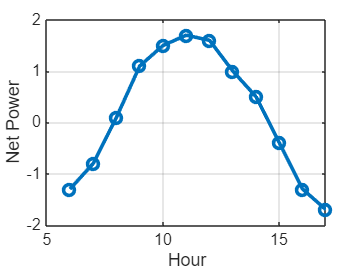


hour = B(:, 1);
solar = B(:, 2);
demand = B(:, 3);
battery = B(:, 4);

netPower = solar - demand;

figure; 
plot(hour, netPower, '-o', 'LineWidth', 2, 'MarkerSize', 6);
grid on;
xlabel('Hour');
ylabel('Net Power');

D = [
    1, 2.1,  8, 12;
    2, 3.4, 13, 19;
    3, 1.8,  7, 10;
    4, 5.2, 21, 31;
    5, 4.7, 19, 28;
    6, 6.0, 25, 36;
    7, 3.1, 12, 18;
    8, 5.8, 24, 35
]

D =     1.0000    2.1000    8.0000   12.0000
    2.0000    3.4000   13.0000   19.0000
    3.0000    1.8000    7.0000   10.0000
    4.0000    5.2000   21.0000   31.0000
    5.0000    4.7000   19.0000   28.0000
    6.0000    6.0000   25.0000   36.0000
    7.0000    3.1000   12.0000   18.0000
    8.0000    5.8000   24.0000   35.0000



writematrix(D, 'drone_delivery.txt');
loaded_D = load('drone_delivery.txt');

DistanceKm = loaded_D(:, 2);
TimeMin = loaded_D(:, 3);
BatteryUsed = loaded_D(:, 4);

speed = DistanceKm ./ TimeMin;
BatteryPerKm = BatteryUsed ./ DistanceKm;
RouteID = loaded_D(:, 1);

idx = BatteryPerKm > 6;
resultMatrix = [RouteID(idx), DistanceKm(idx), BatteryPerKm(idx)]

resultMatrix =     8.0000    5.8000    6.0345


Zone = ["Z1"; "Z2"; "Z3"; "Z4"; "Z5"; "Z6"; "Z7"; "Z8"];
Temp = [22.5; 24.1; 21.8; 25.3; 23.7; 26.0; 22.9; 24.8];
Humidity = [61; 58; 67; 55; 62; 53; 65; 57];
Light = [420; 460; 390; 520; 480; 550; 410; 500];
CO2 = [510; 540; 495; 610; 575; 640; 520; 600];

Farm = table(Zone, Temp, Humidity, Light, CO2)

Farm = 8×5 table
    Zone    Temp    Humidity    Light    CO2
    ____    ____    ________    _____    ___

    "Z1"    22.5       61        420     510
    "Z2"    24.1       58        460     540
    "Z3"    21.8       67        390     495
    "Z4"    25.3       55        520     610
    "Z5"    23.7       62        480     575
    "Z6"      26       53        550     640
    "Z7"    22.9       65        410     520
    "Z8"    24.8       57        500     600


Farm.EnvIndex = 0.4*Farm.Temp + 0.01*Farm.Light + 0.02*Farm.CO2

Farm = 8×6 table
    Zone    Temp    Humidity    Light    CO2    EnvIndex
    ____    ____    ________    _____    ___    ________

    "Z1"    22.5       61        420     510      23.4  
    "Z2"    24.1       58        460     540     25.04  
    "Z3"    21.8       67        390     495     22.52  
    "Z4"    25.3       55        520     610     27.52  
    "Z5"    23.7       62        480     575     25.78  
    "Z6"      26       53        550     640      28.7  
    "Z7"    22.9       65        410     520     23.66  
    "Z8"    24.8       57        500     600     26.92  



idx = Farm.EnvIndex >= 25;
HighEnv = Farm(idx, :)

HighEnv = 5×6 table
    Zone    Temp    Humidity    Light    CO2    EnvIndex
    ____    ____    ________    _____    ___    ________

    "Z2"    24.1       58        460     540     25.04  
    "Z4"    25.3       55        520     610     27.52  
    "Z5"    23.7       62        480     575     25.78  
    "Z6"      26       53        550     640      28.7  
    "Z8"    24.8       57        500     600     26.92  


resultTable = HighEnv(:, {'Zone', 'Temp', 'Light', 'EnvIndex'})

resultTable = 5×4 table
    Zone    Temp    Light    EnvIndex
    ____    ____    _____    ________

    "Z2"    24.1     460      25.04  
    "Z4"    25.3     520      27.52  
    "Z5"    23.7     480      25.78  
    "Z6"      26     550       28.7  
    "Z8"    24.8     500      26.92  


Machine = ["M1"; "M2"; "M3"; "M4"; "M5"; "M6"; "M7"; "M8"; "M9"; "M10"];
Vibration = [1.8; 2.4; 1.5; 3.1; 2.7; 1.9; 3.5; 2.2; 1.6; 2.9];
Temp = [68; 72; 65; 78; 74; 69; 82; 71; 66; 76];
Power = [4.5; 5.1; 4.2; 6.3; 5.7; 4.8; 6.8; 5.0; 4.4; 6.0];
Defect = [2; 5; 1; 8; 6; 3; 10; 4; 1; 7];

Factory = table(Machine, Vibration, Temp, Power, Defect)

Factory = 10×5 table
    Machine    Vibration    Temp    Power    Defect
    _______    _________    ____    _____    ______

     "M1"         1.8        68      4.5        2  
     "M2"         2.4        72      5.1        5  
     "M3"         1.5        65      4.2        1  
     "M4"         3.1        78      6.3        8  
     "M5"         2.7        74      5.7        6  
     "M6"         1.9        69      4.8        3  
     "M7"         3.5        82      6.8       10  
     "M8"         2.2        71        5        4  
     "M9"         1.6        66      4.4        1  
     "M10"        2.9        76        6        7  



Factory.RiskScore =  Factory.Vibration .* Factory.Temp ./ Factory.Power

Factory = 10×6 table
    Machine    Vibration    Temp    Power    Defect    RiskScore
    _______    _________    ____    _____    ______    _________

     "M1"         1.8        68      4.5        2         27.2  
     "M2"         2.4        72      5.1        5       33.882  
     "M3"         1.5        65      4.2        1       23.214  
     "M4"         3.1        78      6.3        8       38.381  
     "M5"         2.7        74      5.7        6       35.053  
     "M6"         1.9        69      4.8        3       27.312  
     "M7"         3.5        82      6.8       10       42.206  
     "M8"         2.2        71        5        4        31.24  
     "M9"         1.6        66      4.4        1           24  
     "M10"        2.9        76        6        7       36.733  


score = (Factory.RiskScore >= 35 & Factory.Defect >= 6);
RiskMachines = Factory(score, :)

RiskMachines = 4×6 table
    Machine    Vibration    Temp    Power    Defect    RiskScore
    _______    _________    ____    _____    ______    _________

     "M4"         3.1        78      6.3        8       38.381  
     "M5"         2.7        74      5.7        6       35.053  
     "M7"         3.5        82      6.8       10       42.206  
     "M10"        2.9        76        6        7       36.733  



resultTable = RiskMachines(:, {'Machine', 'RiskScore', 'Defect'})

resultTable = 4×3 table
    Machine    RiskScore    Defect
    _______    _________    ______

     "M4"       38.381         8  
     "M5"       35.053         6  
     "M7"       42.206        10  
     "M10"      36.733         7  


writetable(Factory, 'factory_risk.csv');

url = "https://archive.ics.uci.edu/ml/machine-learning-databases/abalone/abalone.data";
Abalone = readtable(url, 'FileType', 'text', 'ReadVariableNames', false);
Abalone.Properties.VariableNames = {'Sex', 'Length', 'Diameter', 'Height', ...
    'WholeWeight', 'ShuckedWeight', 'VisceraWeight', 'ShellWeight', 'Rings'};
extractedTable = Abalone(:, {'WholeWeight', 'ShellWeight', 'Rings'});
disp(head(extractedTable, 5));

    WholeWeight    ShellWeight    Rings
    ___________    ___________    _____

       0.514           0.15        15  
      0.2255           0.07         7  
       0.677           0.21         9  
       0.516          0.155        10  
       0.205          0.055         7  




idx = (string(Abalone.Sex) == "M") & (Abalone.Rings >= 15);
OldMale = Abalone(idx, :)

OldMale = 167×9 table
     Sex     Length    Diameter    Height    WholeWeight    ShuckedWeight    VisceraWeight    ShellWeight    Rings
    _____    ______    ________    ______    ___________    _____________    _____________    ___________    _____

    {'M'}    0.455      0.365      0.095        0.514          0.2245            0.101            0.15        15  
    {'M'}    0.605      0.475       0.18       0.9365           0.394            0.219           0.295        15  
    {'M'}    0.665      0.525      0.165        1.338          0.5515           0.3575            0.35        18  
    {'M'}    0.595      0.475       0.16       1.3175           0.408            0.234            0.58        21  
    {'M'}    0.565      0.425      0.135       0.8115           0.341           0.1675           0.255        15  
    {'M'}    0.695       0.56       0.19        1.494           0.588           0.3425           0.485        15  
    {'M'}     0.55      0.435      0.145        0.843    


resultTable = OldMale(:, {'Sex', 'Length', 'WholeWeight', 'Rings'})

resultTable = 167×4 table
     Sex     Length    WholeWeight    Rings
    _____    ______    ___________    _____

    {'M'}    0.455        0.514        15  
    {'M'}    0.605       0.9365        15  
    {'M'}    0.665        1.338        18  
    {'M'}    0.595       1.3175        21  
    {'M'}    0.565       0.8115        15  
    {'M'}    0.695        1.494        15  
    {'M'}     0.55        0.843        15  
    {'M'}     0.53        0.883        15  
    {'M'}      0.7       1.7255        19  
    {'M'}     0.71        1.959        18  
    {'M'}    0.595        1.262        17  
    {'M'}     0.65       1.3445        16  
    {'M'}     0.59        1.053        15  
    {'M'}    0.645        1.514        16  
    {'M'}     0.64        1.368        21  
    {'M'}     0.64       1.3035        16  


Abalone.ShellRatio = Abalone.ShellWeight ./ Abalone.WholeWeight;
idx = (Abalone.ShellRatio >= 0.25) & (Abalone.Rings >= 12);
HardShell = Abalone(idx, :);

disp(head(HardShell, 5));

     Sex     Length    Diameter    Height    WholeWeight    ShuckedWeight    VisceraWeight    ShellWeight    Rings    ShellRatio
    _____    ______    ________    ______    ___________    _____________    _____________    ___________    _____    __________

    {'M'}    0.455      0.365      0.095        0.514          0.2245            0.101           0.15         15       0.29183  
    {'F'}     0.53      0.415       0.15       0.7775           0.237           0.1415           0.33         20       0.42444  
    {'F'}    0.545      0.425      0.125        0.768           0.294           0.1495           0.26         16       0.33854  
    {'F'}     0.55       0.44       0.15       0.8945          0.3145            0.151           0.32         19       0.35774  
    {'F'}    0.525       0.38       0.14       0.6065           0.194           0.1475           0.21         14       0.34625  




resultTable = HardShell(:, {'Sex', 'WholeWeight', 'ShellWeight', 'ShellRatio', 'Rings'})

resultTable = 896×5 table
     Sex     WholeWeight    ShellWeight    ShellRatio    Rings
    _____    ___________    ___________    __________    _____

    {'M'}       0.514           0.15        0.29183       15  
    {'F'}      0.7775           0.33        0.42444       20  
    {'F'}       0.768           0.26        0.33854       16  
    {'F'}      0.8945           0.32        0.35774       19  
    {'F'}      0.6065           0.21        0.34625       14  
    {'M'}      0.6645           0.24        0.36117       12  
    {'F'}      0.9395           0.27        0.28739       12  
    {'M'}       0.931           0.28        0.30075       12  
    {'M'}      0.9365          0.295          0.315       15  
    {'F'}       1.639           0.46        0.28066       15  
    {'M'}       1.338           0.35        0.26158       18  
    {'F'}       1.798          0.455        0.25306       19  
    {'F'}      1.7095           0.49        0.28663       13  
    {'F'}       1.217       


ratioData = HardShell{:, 'ShellRatio'};
disp(ratioData(1:min(10, end)));

    0.2918
    0.4244
    0.3385
    0.3577
    0.3462
    0.3612
    0.2874
    0.3008
    0.3150
    0.2807



clc; clear;
url = "https://archive.ics.uci.edu/ml/machine-learning-databases/forest-fires/forestfires.csv";
ForestFires = readtable(url, 'FileType', 'text', 'ReadVariableNames', true);
disp(head(ForestFires, 5));

    X    Y     month       day      FFMC    DMC      DC      ISI    temp    RH    wind    rain    area
    _    _    _______    _______    ____    ____    _____    ___    ____    __    ____    ____    ____

    7    5    {'mar'}    {'fri'}    86.2    26.2     94.3    5.1     8.2    51    6.7       0      0  
    7    4    {'oct'}    {'tue'}    90.6    35.4    669.1    6.7      18    33    0.9       0      0  
    7    4    {'oct'}    {'sat'}    90.6    43.7    686.9    6.7    14.6    33    1.3       0      0  
    8    6    {'mar'}    {'fri'}    91.7    33.3     77.5      9     8.3    97      4     0.2      0  
    8    6    {'mar'}    {'sun'}    89.3    51.3    102.2    9.6    11.4    99    1.8       0      0  




temp = ForestFires.temp;
RH = ForestFires.RH;
wind = ForestFires.wind;
rain = ForestFires.rain;
area = ForestFires.area;

HotDry = (temp >= 25) & (RH <= 35);
HotDryFires = ForestFires(HotDry, :)

HotDryFires = 54×13 table
    X    Y     month       day      FFMC     DMC      DC      ISI     temp    RH    wind    rain     area 
    _    _    _______    _______    ____    _____    _____    ____    ____    __    ____    ____    ______

    6    5    {'sep'}    {'wed'}    92.9    133.3    699.6     9.2    26.4    21    4.5      0           0
    6    3    {'sep'}    {'sat'}    93.4    145.4    721.4     8.1    30.2    24    2.7      0           0
    6    3    {'sep'}    {'fri'}    94.3     85.1    692.3    15.9    25.4    24    3.6      0           0
    5    6    {'sep'}    {'wed'}    94.3     85.1    692.3    15.9    25.9    24      4      0           0
    4    3    {'sep'}    {'thu'}    92.9      137    706.4     9.2    27.7    24    2.2      0           0
    5    4    {'sep'}    {'fri'}    93.3    141.2    713.9    13.9    27.6    30    1.3      0           0
    1    2    {'sep'}    {'thu'}    92.9      137    706.4     9.2    25.4    27    2.2      0           0
    6    5


resultTable = HotDryFires(:, {'month', 'day', 'temp', 'RH', 'wind', 'area'})

resultTable = 54×6 table
     month       day      temp    RH    wind     area 
    _______    _______    ____    __    ____    ______

    {'sep'}    {'wed'}    26.4    21    4.5          0
    {'sep'}    {'sat'}    30.2    24    2.7          0
    {'sep'}    {'fri'}    25.4    24    3.6          0
    {'sep'}    {'wed'}    25.9    24      4          0
    {'sep'}    {'thu'}    27.7    24    2.2          0
    {'sep'}    {'fri'}    27.6    30    1.3          0
    {'sep'}    {'thu'}    25.4    27    2.2          0
    {'aug'}    {'thu'}    27.4    22      4        0.9
    {'sep'}    {'sat'}    29.6    27    2.7       1.46
    {'sep'}    {'sat'}    28.6    27    2.2       1.61
    {'sep'}    {'sun'}    28.3    26    3.1       64.1
    {'sep'}    {'wed'}    26.4    21    4.5      88.49
    {'sep'}    {'sun'}    27.8    27    3.1      95.18
    {'sep'}    {'sat'}    25.1    27      4     1090.8
    {'aug'}    {'wed'}    28.7    28    2.7          0
    {'aug'}    {'wed'}    26.8    25   

Fire = ForestFires;
Fire.RiskIndex = Fire.temp .* Fire.wind ./ Fire.RH;
idx = (Fire.RiskIndex >= 2) & (Fire.area >0);
RiskFire = Fire(idx, :)

RiskFire = 105×14 table
    X    Y     month       day      FFMC     DMC      DC      ISI     temp    RH    wind    rain    area    RiskIndex
    _    _    _______    _______    ____    _____    _____    ____    ____    __    ____    ____    ____    _________

    1    2    {'aug'}    {'wed'}    95.5     99.9    513.3    13.2    23.3    31    4.5      0      0.55     3.3823  
    8    6    {'aug'}    {'fri'}    90.1      108    529.8    12.5    21.2    51    8.9      0      0.61     3.6996  
    2    5    {'aug'}    {'wed'}    95.5     99.9    513.3    13.2    23.8    32    5.4      0      0.77     4.0163  
    6    5    {'aug'}    {'thu'}    95.2    131.7    578.8    10.4    27.4    22      4      0       0.9     4.9818  
    8    3    {'sep'}    {'tue'}    84.4     73.4    671.9     3.2    24.2    28    3.6      0      0.96     3.1114  
    2    2    {'aug'}    {'tue'}    94.8    108.3    647.1      17    17.4    43    6.7      0      1.07     2.7112  
    8    6    {'sep'}    {'thu'


resultTable = RiskFire(:, {'month', 'day', 'temp', 'RH', 'wind', 'area', 'RiskIndex'})

resultTable = 105×7 table
     month       day      temp    RH    wind    area    RiskIndex
    _______    _______    ____    __    ____    ____    _________

    {'aug'}    {'wed'}    23.3    31    4.5     0.55     3.3823  
    {'aug'}    {'fri'}    21.2    51    8.9     0.61     3.6996  
    {'aug'}    {'wed'}    23.8    32    5.4     0.77     4.0163  
    {'aug'}    {'thu'}    27.4    22      4      0.9     4.9818  
    {'sep'}    {'tue'}    24.2    28    3.6     0.96     3.1114  
    {'aug'}    {'tue'}    17.4    43    6.7     1.07     2.7112  
    {'sep'}    {'thu'}    23.7    25    4.5     1.12      4.266  
    {'jun'}    {'fri'}    23.2    39    5.4     1.19     3.2123  
    {'sep'}    {'fri'}    20.1    47    4.9     1.46     2.0955  
    {'sep'}    {'sat'}    29.6    27    2.7     1.46       2.96  
    {'sep'}    {'sat'}    28.6    27    2.2     1.61     2.3304  
    {'aug'}    {'wed'}    20.5    35      4     1.64     2.3429  
    {'sep'}    {'fri'}      19    34    5.8     1

writetable(RiskFire, 'forest_risk.csv');

opts = detectImportOptions('penguins_lter.csv');
opts.VariableNamingRule = 'preserve';

P = readtable('penguins_lter.csv', opts);
P.Properties.VariableNames

ans = 1×17 cell 배열
    {'studyName'}    {'Sample Number'}    {'Species'}    {'Region'}    {'Island'}    {'Stage'}    {'Individual ID'}    {'Clutch Completion'}    {'Date Egg'}    {'Culmen Length (mm)'}    {'Culmen Depth (mm)'}    {'Flipper Length (mm)'}    {'Body Mass (g)'}    {'Sex'}    {'Delta 15 N (o/oo)'}    {'Delta 13 C (o/oo)'}    {'Comments'}



P.Properties.VariableNames{'Species'} = 'species';
P.Properties.VariableNames{'Island'} = 'island';
P.Properties.VariableNames{'Culmen Length (mm)'} = 'bill_length_mm';
P.Properties.VariableNames{'Culmen Depth (mm)'} = 'bill_depth_mm';
P.Properties.VariableNames{'Flipper Length (mm)'} = 'flipper_length_mm';
P.Properties.VariableNames{'Body Mass (g)'} = 'body_mass_g';
P.Properties.VariableNames{'Sex'} = 'sex';

P_filtered = P(P.body_mass_g >= 4500, :);
result_table = P_filtered(:, {'species', 'island', 'body_mass_g', 'sex'})

result_table = 118×4 table
                       species                          island        body_mass_g       sex    
    _____________________________________________    _____________    ___________    __________

    {'Adelie Penguin (Pygoscelis adeliae)'      }    {'Torgersen'}       4675        {'MALE'  }
    {'Adelie Penguin (Pygoscelis adeliae)'      }    {'Torgersen'}       4500        {'MALE'  }
    {'Adelie Penguin (Pygoscelis adeliae)'      }    {'Dream'    }       4650        {'MALE'  }
    {'Adelie Penguin (Pygoscelis adeliae)'      }    {'Dream'    }       4600        {'MALE'  }
    {'Adelie Penguin (Pygoscelis adeliae)'      }    {'Torgersen'}       4700        {'MALE'  }
    {'Adelie Penguin (Pygoscelis adeliae)'      }    {'Biscoe'   }       4725        {'MALE'  }
    {'Adelie Penguin (Pygoscelis adeliae)'      }    {'Biscoe'   }       4775        {'MALE'  }
    {'Adelie Penguin (Pygoscelis adeliae)'      }    {'Biscoe'   }       4600        {'MALE'  }
    {'Chinst


isGentoo = contains(P.species, 'Gentoo'); 
isHeavy = P.body_mass_g >= 5000;

LargeGentoo = P(isGentoo & isHeavy, :);

P.BillRatio = P.("bill_length_mm") ./ P.("bill_depth_mm");
LongBill = P(P.BillRatio >= 2.8, :);

result_table = LongBill(:, {'species', 'bill_length_mm', 'bill_depth_mm', 'BillRatio'})

result_table = 131×4 table
                       species                       bill_length_mm    bill_depth_mm    BillRatio
    _____________________________________________    ______________    _____________    _________

    {'Chinstrap penguin (Pygoscelis antarctica)'}         51.3             18.2          2.8187  
    {'Chinstrap penguin (Pygoscelis antarctica)'}           52             18.1          2.8729  
    {'Chinstrap penguin (Pygoscelis antarctica)'}           58             17.8          3.2584  
    {'Chinstrap penguin (Pygoscelis antarctica)'}         47.5             16.8          2.8274  
    {'Chinstrap penguin (Pygoscelis antarctica)'}         46.9             16.6          2.8253  
    {'Chinstrap penguin (Pygoscelis antarctica)'}         50.9             17.9          2.8436  
    {'Chinstrap penguin (Pygoscelis antarctica)'}         49.8             17.3          2.8786  
    {'Chinstrap penguin (Pygoscelis antarctica)'}         48.1             16.4          2


billRatioData = P{:, 'BillRatio'}

billRatioData =     2.0909
    2.2701
    2.2389
       NaN
    1.9016
    1.9078
    2.1854
    2.0000
    1.8840
    2.0792


clc; clear;
opts = detectImportOptions('heart_failure_clinical_records_dataset.csv');
opts.VariableNamingRule = 'preserve'; 
H = readtable('heart_failure_clinical_records_dataset.csv', opts);

current_names = H.Properties.VariableNames;

H.Properties.VariableNames{find(contains(current_names, 'age', 'IgnoreCase', true), 1)} = 'age';
H.Properties.VariableNames{find(contains(current_names, 'ejection', 'IgnoreCase', true), 1)} = 'ejection_fraction';
H.Properties.VariableNames{find(contains(current_names, 'creatinine', 'IgnoreCase', true), 1)} = 'serum_creatinin';
H.Properties.VariableNames{find(contains(current_names, 'sodium', 'IgnoreCase', true), 1)} = 'serum_sodium';
H.Properties.VariableNames{find(contains(current_names, 'death', 'IgnoreCase', true), 1)} = 'DEATH_EVENT';

isOld = H.age >= 70;
isLowFraction = H.ejection_fraction <= 35;

HighRisk = H(isOld & isLowFraction, :);
result_table = HighRisk(:, {'age', 'ejection_fraction', 'serum_creatinin', 'serum_sodium', 'DEATH_EVENT'})

result_table = 31×5 table
    age    ejection_fraction    serum_creatinin    serum_sodium    DEATH_EVENT
    ___    _________________    _______________    ____________    ___________

    75            20                  582              130              1     
    75            15                  246              137              1     
    80            35                  123              133              1     
    70            25                  125              140              1     
    75            30                  582              134              1     
    82            30                   70              132              1     
    70            20                  582              134              1     
    80            20                  553              133              1     
    95            30                  371              132              1     
    70            35                   75              138              0     
    72            20     


DeathGroup = H(H.DEATH_EVENT == 1, :);
SurvivalGroup = H(H.DEATH_EVENT == 0, :);

H.RiskScore = H.age ./ H.ejection_fraction + H.serum_creatinine;

idx = H.RiskScore >= 4;
RiskScoreGroup = H(idx, :);
result_table = RiskScoreGroup(:, {'age', 'ejection_fraction', 'serum_creatinine', 'RiskScore', 'DEATH_EVENT'})

result_table = 59×5 table
    age    ejection_fraction    serum_creatinine    RiskScore    DEATH_EVENT
    ___    _________________    ________________    _________    ___________

    75            20                   1.9             5.65           1     
    65            20                   1.3             4.55           1     
    50            20                   1.9              4.4           1     
    65            20                   2.7             5.95           1     
    90            40                   2.1             4.35           1     
    75            15                   1.2              6.2           1     
    80            35                   9.4           11.686           1     
    75            38                     4           5.9737           1     
    45            14                   0.8           4.0143           1     
    75            30                  1.83             4.33           1     
    80            38                   1.9       

writetable(RiskScoreGroup, 'heart_risk_group.csv');

clear; clc;
opts = detectImportOptions('bank.csv');
B = readtable('bank.csv', opts);
B.Properties.VariableNames

ans = 1×17 cell 배열
    {'age'}    {'job'}    {'marital'}    {'education'}    {'default'}    {'balance'}    {'housing'}    {'loan'}    {'contact'}    {'day'}    {'month'}    {'duration'}    {'campaign'}    {'pdays'}    {'previous'}    {'poutcome'}    {'deposit'}



B.Properties.VariableNames{strcmp(B.Properties.VariableNames, 'deposit')} = 'y';
age = B.age;
balance = B.balance;
loan = B.loan;
y = B.y;

idx_T1 = (age >= 40) & (balance >= 2000) & (string(loan) == "no");
T1 = B(idx_T1, :);

T2 = T1(:, {'age', 'balance', 'y'});

T2.NewFlag = double(string(T2.y) == "yes");

idx_sub = T2.NewFlag == 1;
Subscribed = T2(idx_sub, :);

balanceVec = Subscribed{:, 'balance'};

avgBalance = mean(balanceVec)

avgBalance = 5.3956e+03


writetable(Subscribed, 'bank_selected.csv');